## Hectareas por año

data_result=[];
indice=1;
for eage=2003:2022
    indxs=find(info_hdf.anio==eage);
    
    datos=arr_ndvi_sgf(:,:,indxs);
    

% %       data_tab_function=f_aplica_formulas(datos,study_area,1);
%     data_tab_function=f_training_data(datos,study_area,1);


    
% %     data_ndvi=data_tab_function(:,1:8);
%     data_ndvi=data_tab_function(:,1);


% --------------------------------------------------TEMP
    [~,~,pix_tam] =size(datos);
    
    d_res_tmp=[];

    for pxi_i=1:pix_tam
        data_tab_function=f_training_data(datos(:,:,pxi_i),study_area,1);  
        t_pxi=table2array(data_tab_function(:,1));
        d_res_tmp=[d_res_tmp,t_pxi];
    end

% --------------------------------------------------
    class_result=model_entrenado.predictFcn(d_res_tmp);

%     area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);
    
%     pix_area=sum(area_naranja,"all");
    pix_area=sum(class_result)
    
    data_result(indice)=pix_area*6.25;
%     data_result(indice)=pix_area;

   indice=indice+1;
end

pix_area =        21921


pix_area =        18861


pix_area =        17935


pix_area =        20266


pix_area =        24954


pix_area =        18107


pix_area =        21680


pix_area =        17159


pix_area =        20144


pix_area =        16059


pix_area =        18420


pix_area =        21936


pix_area =        21202


pix_area =        14219


pix_area =        17343


pix_area =        20564


pix_area =        21812


pix_area =        14448


pix_area =        20662


pix_area =        19191


## Data result

figure 
hold on;

eage_x=2003:2022;
format long;
idx_municipio=4;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
% 
% plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
% title(data_production(idx_municipio).Municipio);
plot(eage_x, data_result)
legend("Sembrado", "Red Neuronal","Location","south");


title("Comparacion de resultados",data_production(idx_municipio).Municipio);
xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
ax = gca;
ax.FontSize=18; 

err=immse(data_production(idx_municipio).Superficie_sembrada_Ha,data_result)

err =      4.525306805000000e+07


fprintf('MAE: %.4f\n', err);

MAE: 45253068.0500


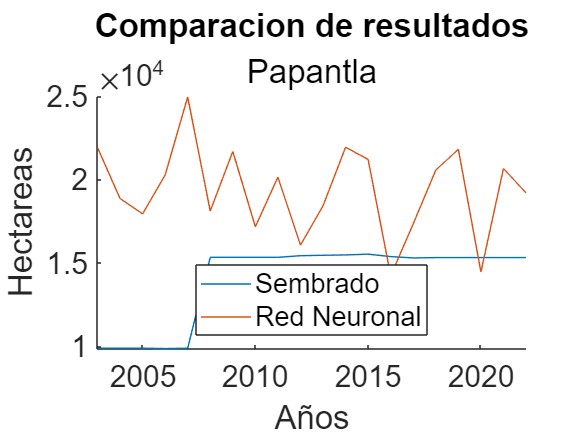

hold off


figure
hold on
plot(eage_x,data_result)

disp("error cuadratico medio")

error cuadratico medio


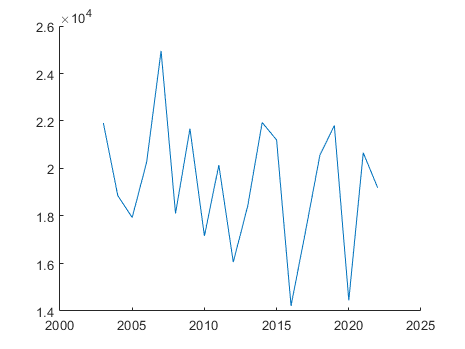

hold off

## Marcar zonas

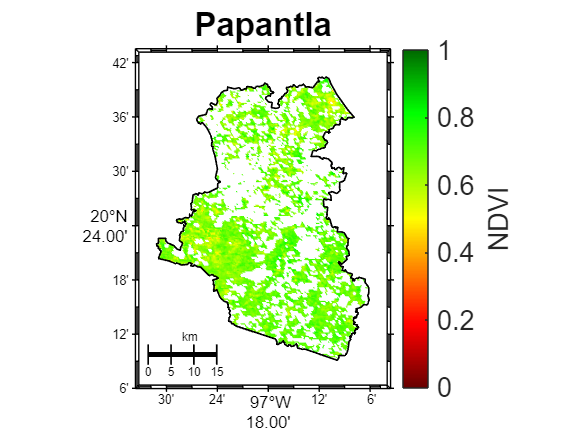

indxs=find(info_hdf.anio==2022);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);

[~,~,pix_tam] =size(datos);
    
    d_res_tmp=[];

    for pxi_i=1:pix_tam
        data_tab_function=f_training_data(datos(:,:,pxi_i),study_area,1);  
        t_pxi=table2array(data_tab_function(:,1));
        d_res_tmp=[d_res_tmp,t_pxi];
    end

% % ----------------------------------------------------------------------

class_result=model_entrenado.predictFcn(d_res_tmp);


area_naranja=f_make_area(datos,class_result,study_area);

area_clasificada=datos;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 